# Simulate Physical Model

## Open Model

modelName = 'simpleHelicopter_toReduce';
open_system(modelName)
train = true; % enable or disable network trainning

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the the heat input stairs

initialScenarioVector = [[2e3:1e3:5e3] [5e3:-1e3:2.5e3]];
referenceHeatStates = {{initialScenarioVector,simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+150],simStopTime},                       
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+300],simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+450], simStopTime},
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+600],simStopTime}, 
                    {[initialScenarioVector(1), initialScenarioVector(2:end)+650], simStopTime}};

Generate the simulation scenarios and save them in MAT files

for ix=1:numel(referenceHeatStates)
    generateInputs(scenarioDir, referenceHeatStates{ix}{1},...
    referenceHeatStates{ix}{2}, ix, 'heatIn')
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

load_system(modelName)
clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
simIn(1:numCases) = Simulink.SimulationInput(modelName);

for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    scenarioSimStopTime = aux{end};

    simIn(ix) = simIn(ix).setModelParameter('StopTime', scenarioSimStopTime);
    simIn(ix) = setVariable(simIn(ix), 'Qin', scenario{ix}.stateVecRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'Qin_time', scenario{ix}.stateVecRef{1}.Values.Time', ...
        'Workspace', modelName);
end

## Simulate

Simulate in parallel and save the results

out = parsim(simIn);

[28-Oct-2023 22:12:17] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
[28-Oct-2023 22:12:45] Starting Simulink on parallel workers...
[28-Oct-2023 22:12:59] Loading project on parallel workers...
[28-Oct-2023 22:12:59] Configuring simulation cache folder on parallel workers...
[28-Oct-2023 22:13:09] Loading model on parallel workers...
[28-Oct-2023 22:13:18] Running simulations...
[28-Oct-2023 22:17:41] Completed 1 of 12 simulation runs
[28-Oct-2023 22:17:41] Completed 2 of 12 simulation runs
[28-Oct-2023 22:18:58] Completed 3 of 12 simulation runs
[28-Oct-2023 22:18:58] Completed 4 of 12 simulation runs
[28-Oct-2023 22:18:59] Completed 5 of 12 simulation runs
[28-Oct-2023 22:18:59] Completed 6 of 12 simulation runs
[28-Oct-2023 22:18:59] Completed 7 of 12 simulation runs
[28-Oct-2023 22:18:59] Completed 8 of 12 simulation runs
[28-Oct-2023 22:19:11] Completed 9 of 12 simulatio

save(fullfile(simOutDir,'simOuts'),'out') 

# Prepare Data for Training

To achieve better performance the data are resampled, normalized.

## Resample Data

Resample the date in seconds

sampleTime = 0.1; % s
commandSignals = [{'Altitude', 'Qin'}];
[resampledData, sigNames] = resampleSimulationData(out,sampleTime,commandSignals);

## Visualize Resampled data

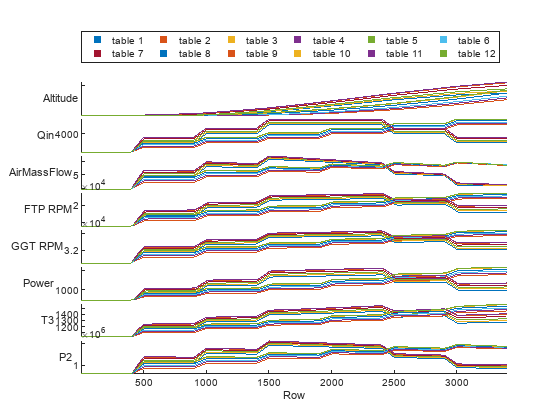

figure
t = cellfun(@(x) array2table(x', VariableNames=sigNames), resampledData, UniformOutput=false);
stackedplot(t{:})

## Prepare Data For Training

trainPercentage = 1; % the percentage of the data that they will be used for training
                       % the rest will be used for test
[dataTrain, dataTest, meanTrain, stdTrain] = prepareDataNormalization(resampledData, trainPercentage);
save meanTrain meanTrain
save stdTrain stdTrain

## Normalize Data

Apply gaussian normalization to the entire set of data.

*PH: zscore, cellfun*

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNormComp = cellfun(@(x) normalize(x, meanTrain', stdTrain'), dataTrain, 'UniformOutput', false)

# Train a Neural Network

*PH: consider using trainnet*

## Define the Inputs/Outputs

Define the number of inputs and outputs of the neural network. Create respective datasets that correspond to the inputs and outputs of each timestep.

numFeatures = length(sigNames);
numResponses = length(sigNames)-length(commandSignals);
outStartIdx = length(commandSignals)+1;
numHiddenUnits = 150;
dropoutProbability = 0.2;

[XTrainSep, TTrainSep] = preprocessTrainData(dataTrainNorm, outStartIdx);

## Define Network Architecture

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    % regressionLayer("Name","regressionoutput")
    ];


## Define Training Options

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

## Train the Network

*PH: Envoyer des donnes*

if train
    [net, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers,opts);
    net = resetState(net);
end

for ix=1:numel(XTrainSep)
XTrainSepReversed{ix} = XTrainSep{ix}';
TTrainSepReversed{ix} = TTrainSep{ix}';

end

nnet = trainnet(XTrainSepReversed,TTrainSepReversed,layers,'mean-squared-error',opts)

## Integrate Trained LSTM Network in Simulink

You can use recurrent neural networks in simulink by using the "Stateful Predict" block 

reducedModel = 'simpleHelicopter_ROM';
open_system(reducedModel)

# Evaluate results

Compare original and reduced model rregarding their resutls and simulation performance. This comparison is in a scenario that has not been included in the trainning.

mode = 'Custom';

## Simulate the ROM

set_param([reducedModel,'/HeatIn'],'LabelModeActivechoice', mode)
romSim = sim(reducedModel);
romRunID = Simulink.sdi.Run.getLatest;

## Simulate the Physical Model

referenceModel = 'simpleHelicopter_reference';
open_system(referenceModel)
set_param([referenceModel,'/HeatIn'],'LabelModeActivechoice', mode)
refSim = sim(referenceModel);
refRunID = Simulink.sdi.Run.getLatest;

## Compare with Simulink Test

import matlab.unittest.TestCase
import Simulink.sdi.constraints.MatchesSignal
import Simulink.sdi.constraints.MatchesSignalOptions

Create a test case:

testCase = TestCase.forInteractiveUse;    

Set the accepted relative and absolute tolerance:

relTol = 1e-2;
absTol = 6;

Compare different signals between ROM LSTM model and original model.

for ix=1:length(sigNames)
    basselineSig = refSim.logsout.getElement(sigNames{ix});
    romSig = romSim.logsout.getElement(sigNames{ix});
    testCase.verifyThat(romSig,MatchesSignal(basselineSig,'RelTol',relTol))
end

## Visualize in Simulation Data Inspector

Simulink.sdi.compareRuns(refRunID.id,romRunID.id,'RelTol',relTol,'AbsTol',absTol)
Simulink.sdi.view

## Performance comparison

*KR: focus in the results*

Compare the Simulation Metadata containing information regarding the initialization, execution and total time of the simulation.

The timing info for the reference simulation

refSim.SimulationMetadata.TimingInfo

The timing info for the ROM model

romSim.SimulationMetadata.TimingInfo

Compare performance:

compareSimulationPerformance(refSim, romSim)

# Real-Time Simulation

KR: Speedgoat

Use Simulink Desktop Real-Time to simulate the model in real time:

open_system('simpleHelicopter_ROM_realTime')

 Let's take-off !